# **Hydrogen Atom Orbitals**

**https://ww2.mathworks.cn/matlabcentral/fileexchange/81733-how-to-plot-hydrogen-orbitals**

`by Jonas Tjepkema`

### **1) ****Spherical Harmonics****:**

**Plotting the associated Legendre Polynomial**

You can find the functions at the end of this live script.

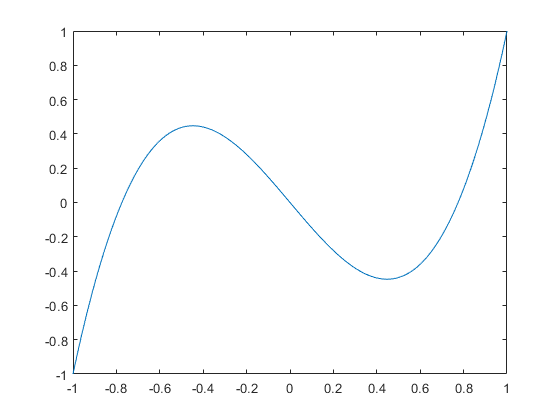

x1 = linspace(-1,1,1000);
g1 = AssocLegPol(0,3);
figure()
plot(x1,g1(x1))

**Computing the Spherical Harmonics**

theta = linspace(0,2*pi,1000);
phi = linspace(-pi,pi,1000);

Y = SphericalHarm(theta,phi,1,1)

Y =    0.0000 + 0.0000i   0.0022 + 0.0000i   0.0043 + 0.0001i   0.0065 + 0.0001i   0.0087 + 0.0002i   0.0109 + 0.0003i   0.0130 + 0.0005i   0.0152 + 0.0007i   0.0174 + 0.0009i   0.0195 + 0.0011i   0.0217 + 0.0014i   0.0238 + 0.0017i   0.0260 + 0.0020i   0.0281 + 0.0023i   0.0303 + 0.0027i   0.0324 + 0.0031i   0.0345 + 0.0035i   0.0367 + 0.0039i   0.0388 + 0.0044i   0.0409 + 0.0049i   0.0430 + 0.0054i   0.0451 + 0.0060i   0.0472 + 0.0066i   0.0493 + 0.0072i   0.0514 + 0.0078i   0.0534 + 0.0085i   0.0555 + 0.0092i   0.0575 + 0.0099i   0.0596 + 0.0106i   0.0616 + 0.0114i   0.0637 + 0.0122i   0.0657 + 0.0130i   0.0677 + 0.0138i   0.0697 + 0.0147i   0.0716 + 0.0156i   0.0736 + 0.0165i   0.0756 + 0.0174i   0.0775 + 0.0184i   0.0795 + 0.0194i   0.0814 + 0.0204i   0.0833 + 0.0214i   0.0852 + 0.0225i   0.0871 + 0.0236i   0.0889 + 0.0247i   0.0908 + 0.0258i   0.0926 + 0.0269i   0.0945 + 0.0281i   0.0963 + 0.0293i   0.0981 + 0.0305i   0.0999 + 0.0318i


The values above are correct, but without the right type of grid and basis, we cannot visualize the shape of the harmonics. For that we will use a mesh grid:

theta = linspace(0,pi,100);
phi = linspace(0,2*pi,100);
[theta,phi] = meshgrid(theta,phi);

m = 3;
l = 4;

Y = SphericalHarmRealBasis(theta,phi,m,l);

Now the spherical harmonic is stored as a matrix of values for each theta and phi. We now want to convert everything back to cartesian coordinates:

x= abs(Y).*sin(theta).*cos(phi);
y = abs(Y).*sin(theta).*sin(phi);
z = abs(Y).*cos(theta);

And plot,

**Mesh function**:

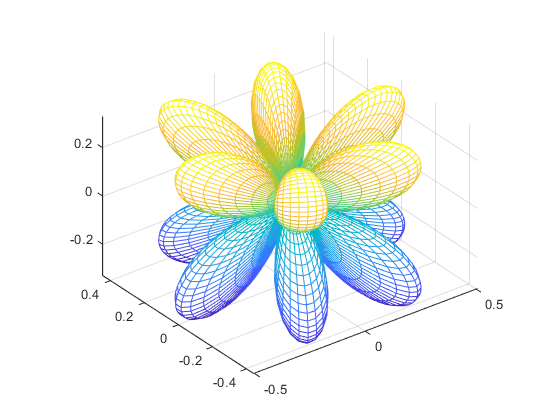

figure()
mesh(x,y,z)
axis equal

**Surf function**:

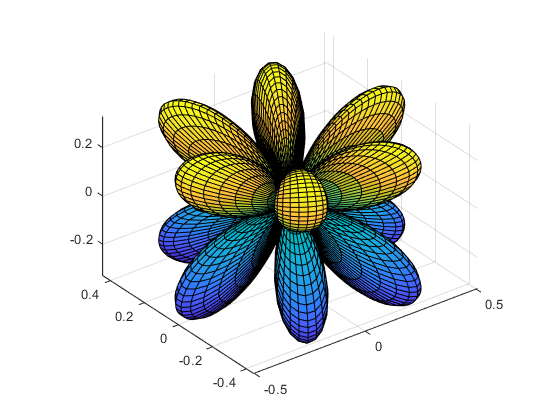

figure()
surf(x,y,z)
axis equal
axis vis3d;

### **2) ****Radial Harmonics****: **

**Plotting the associated Laguerre Polynomial**

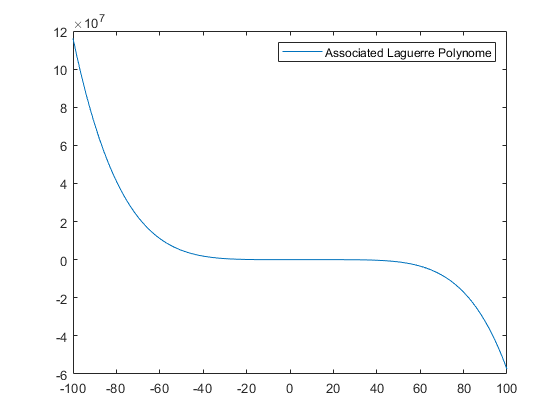

x2 = linspace(-100,100,100);
g2 = AssocLaguPol(2,5);
figure()
plot(x2,g2(x2))
legend("Associated Laguerre Polynome")

**Computing the Radial Harmonics**

r = linspace(0,100,100);
R = RadialHarm(r,2,0)

R =     0.7071    0.2112   -0.0026   -0.0801   -0.0957   -0.0863   -0.0693   -0.0523   -0.0378   -0.0266   -0.0183   -0.0125   -0.0083   -0.0055   -0.0036   -0.0024   -0.0015   -0.0010   -0.0006   -0.0004   -0.0003   -0.0002   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


### 3) Plotting The Orbitals of the Hydrogen Atom

We now have all the tools to plot our PDF of the wave function! We can create Psi by just multiplying the two harmonics together and that we can then put psi squared into the isosurface function as to find the orbitals for a certain probability. 

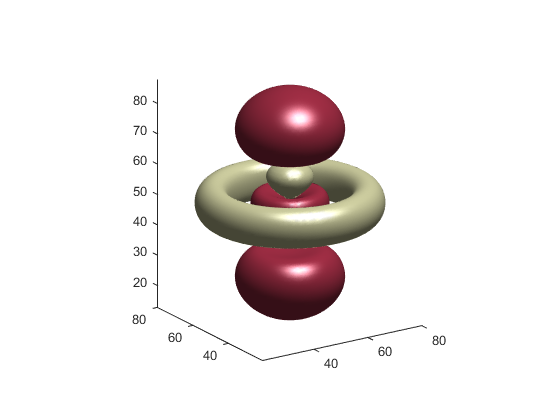

grid = linspace(-40, 40, 100);
[x, y, z] = meshgrid(grid, grid, grid);

r = sqrt(x.^2 + y.^2 + z.^2);
theta = acos(z ./ r);
phi = atan2(y, x);

n=4;
l=2;
m=0;
probd = 1e-5;

psi = SphericalHarmRealBasis(theta,phi,m,l) .* RadialHarm(r,n,l);

figure()
isosurface(psi.^2,probd,sign(psi))

% columns are R G B
% rows are the different levels from high to low
map = [.7 .2 .3
    .9 .9 .7];

colormap(map)
axis equal
axis vis3d;

### ***Function Library***

***Functions for the spherical harmonics part:***

function p = AssocLegPol(m,l)
    syms x;
    expr = (x^2-1)^l;
    
    f = diff(expr,l+m);
        
    AssociatedLeg = (((-1)^m)/(2^l*factorial(l)))*((1-x^2)^(m/2))*f;

    p = matlabFunction(AssociatedLeg);
end

function Y = SphericalHarm(theta,phi,m,l)
    g = AssocLegPol(m,l);
    Y = sqrt(((2*l+1)/(4*pi)).*(factorial(l-abs(m))/factorial(l+abs(m)))).*exp(1i*m*phi).*g(cos(theta));
end

function Y = SphericalHarmRealBasis(theta,phi,m,l)
    if (m < 0)
        Y = sqrt(2) * (-1)^m * imag(SphericalHarm(theta,phi,abs(m),l));
    elseif (m == 0)
        Y = SphericalHarm(theta, phi, m, l);
    else
        Y = sqrt(2) * (-1)^m * real(SphericalHarm(theta, phi, m, l));
    end
end

***Functions for the radial harmonics part:***

function p = AssocLaguPol(p,q)
    syms x;
    expr = exp(-x)*x^(p+q);
    
    if q == 0
        f = expr;
    else
        f = diff(expr,q);
    end
   
    AssociatedLag = (x^(-p)*exp(x))/factorial(q)*f;
    
    p = matlabFunction(simplify(AssociatedLag));
end

function R = RadialHarm(r,n,l)
    a = 1; %5.29e-11;
    g = AssocLaguPol(2*l+1,n-l-1);
    if n-l-1 == 0
        G = 1;
    else
        G = g(2*r/(n*a));
    end
    R = sqrt((2/(n*a)).^3*factorial(n-l-1)/(2*n*factorial(n+l))).*exp(-r/(n*a)).*(2*r/(n*a)).^l.*G;
end